## 7.3

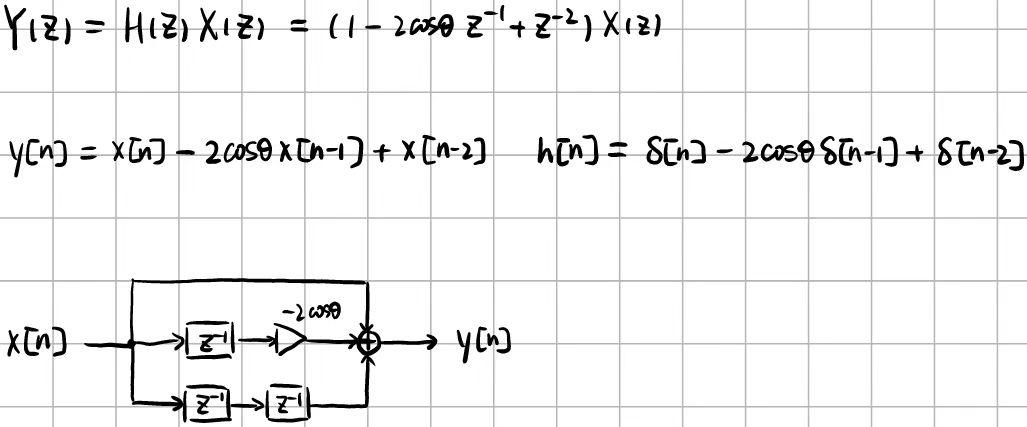

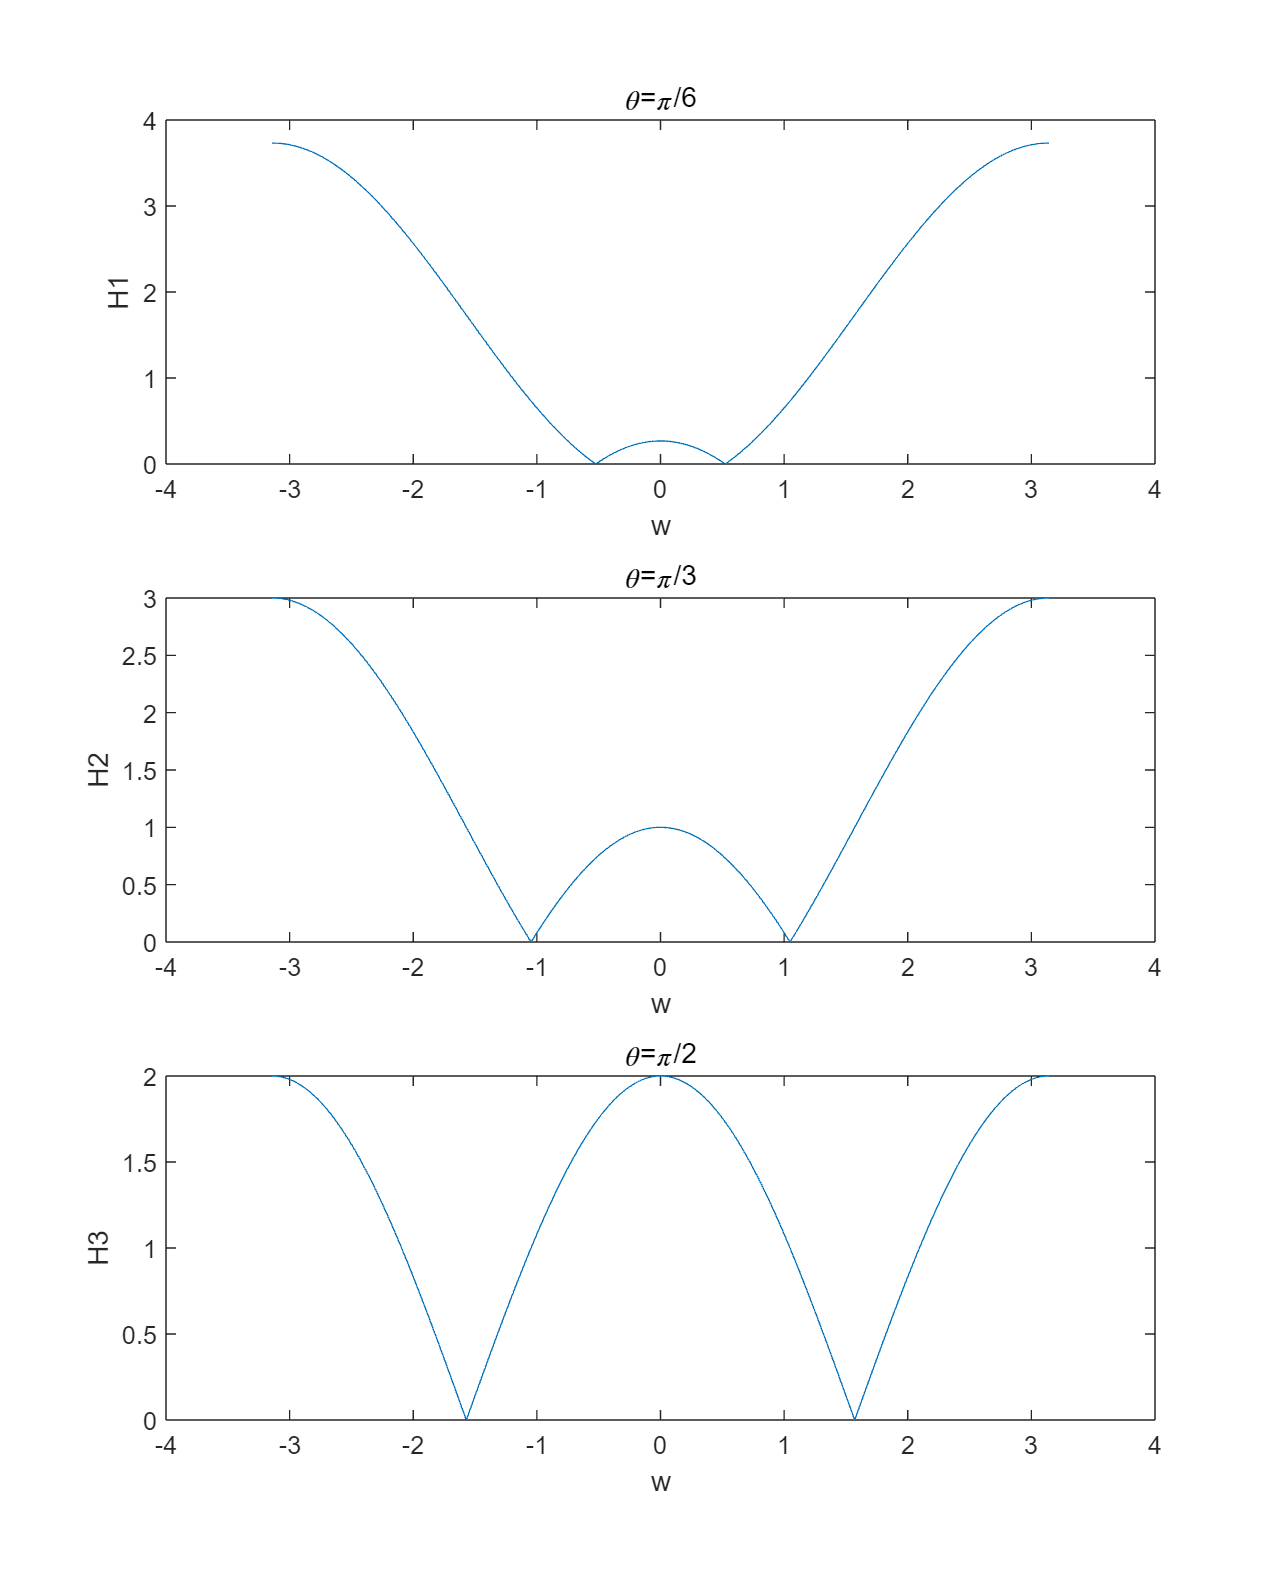

w = linspace(-pi,pi,1000);
z = exp(-1j*w);
H1 = 1 - 2*cos(pi/6)*z.^(-1)+z.^(-2);
H2 = 1 - 2*cos(pi/3)*z.^(-1)+z.^(-2);
H3 = 1 - 2*cos(pi/2)*z.^(-1)+z.^(-2);
figure('Position', [100 100 800 1000]);
subplot(311),plot(w,abs(H1)),xlabel('w'),ylabel('H1'),title('\theta=\pi/6');
subplot(312),plot(w,abs(H2)),xlabel('w'),ylabel('H2'),title('\theta=\pi/3');
subplot(313),plot(w,abs(H3)),xlabel('w'),ylabel('H3'),title('\theta=\pi/2');

w=θ, H=0; θ increases, maximum decreses, low frequency component increses

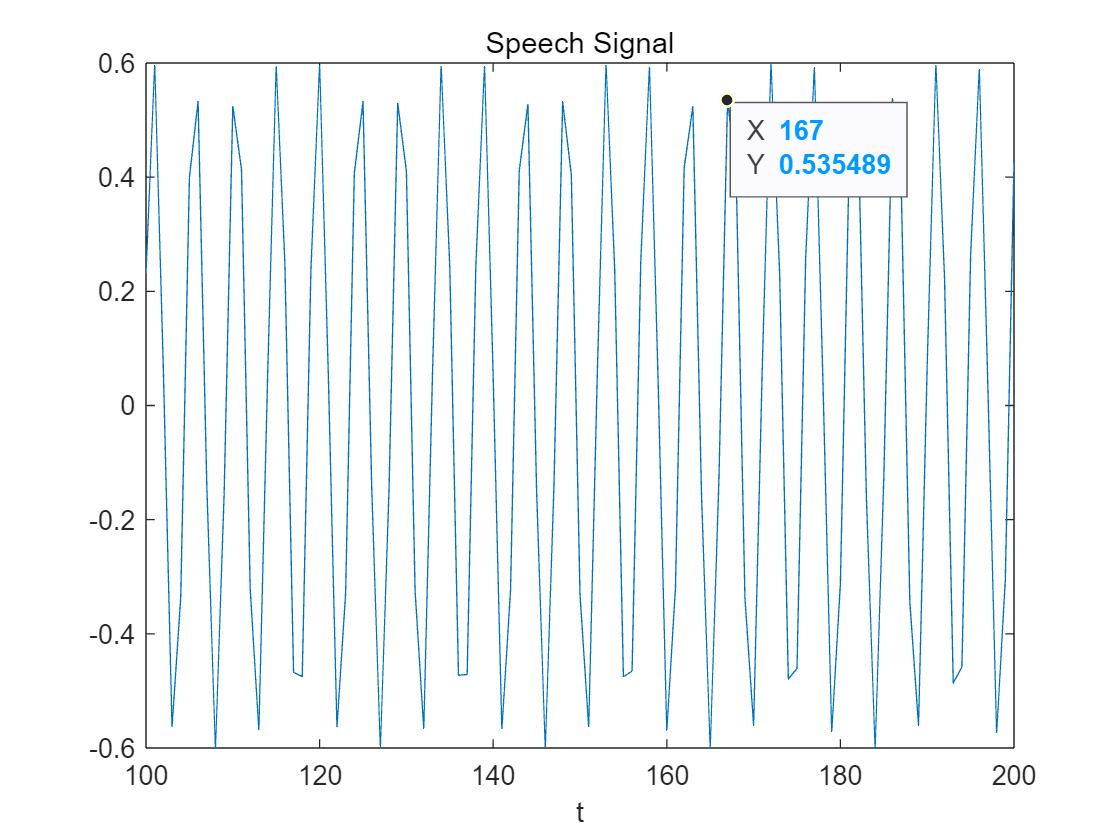

load nspeech1.mat;
sound(nspeech1);
figure;
plot(100:200,nspeech1(100:200)),xlabel('t'),title('Speech Signal');

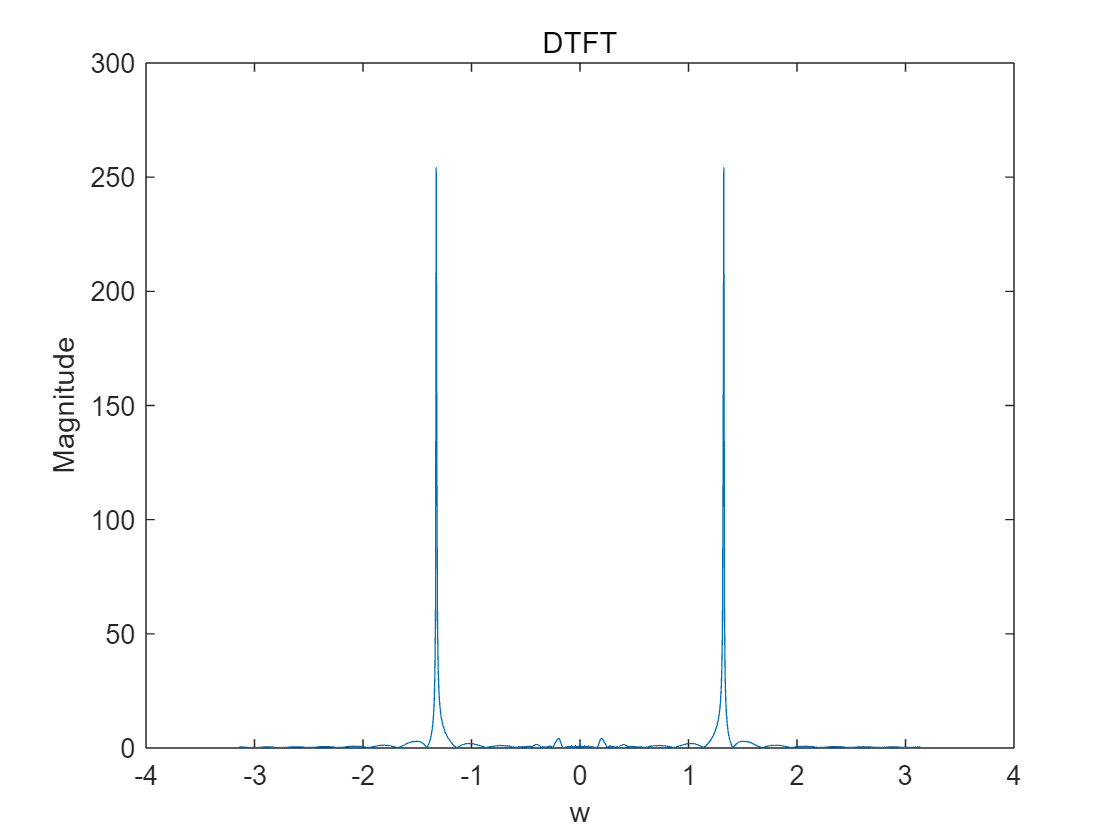

[X,w]=DTFT(nspeech1(100:1100),0);
figure;
plot(w,abs(X)),xlabel('w'),ylabel('Magnitude'),title('DTFT');

[Xmax,Imax] = maxk(abs(X),2);
theata = w(Imax)

theata =    -1.3254    1.3254


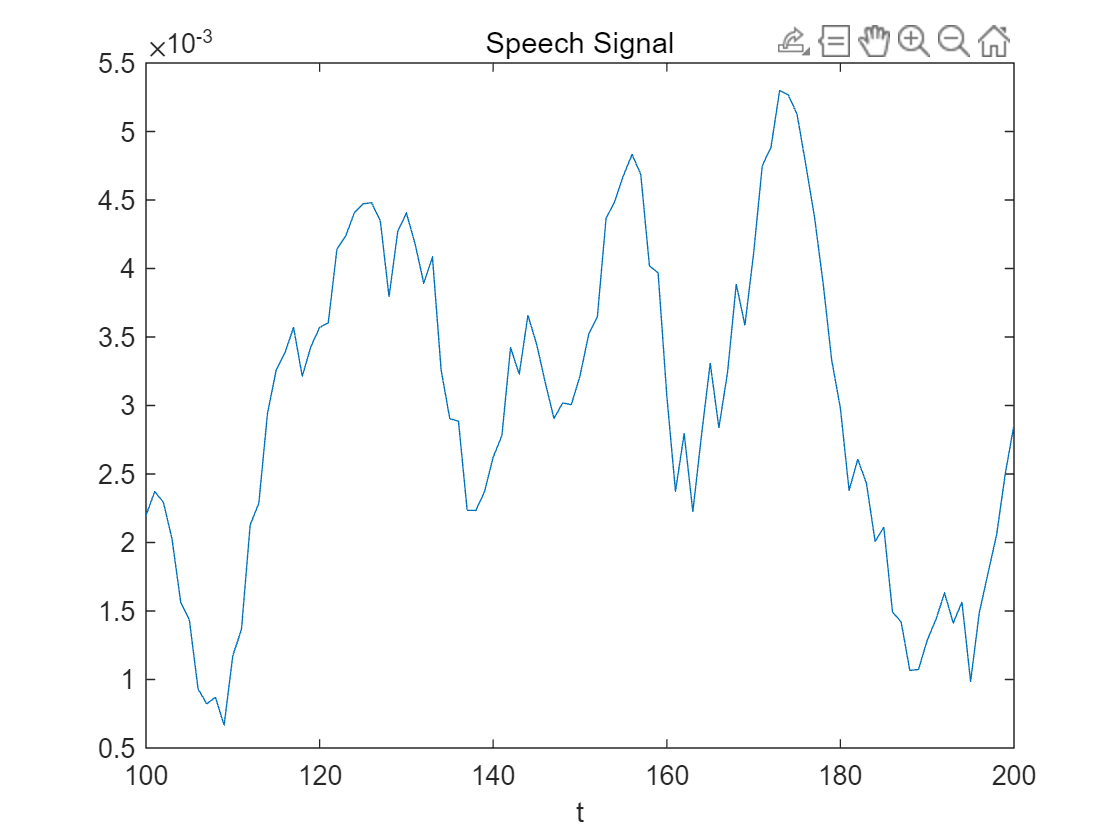

nspeech1 = FIRfilter(nspeech1);
sound(nspeech1);
figure;
plot(100:200,nspeech1(100:200)),xlabel('t'),title('Speech Signal');

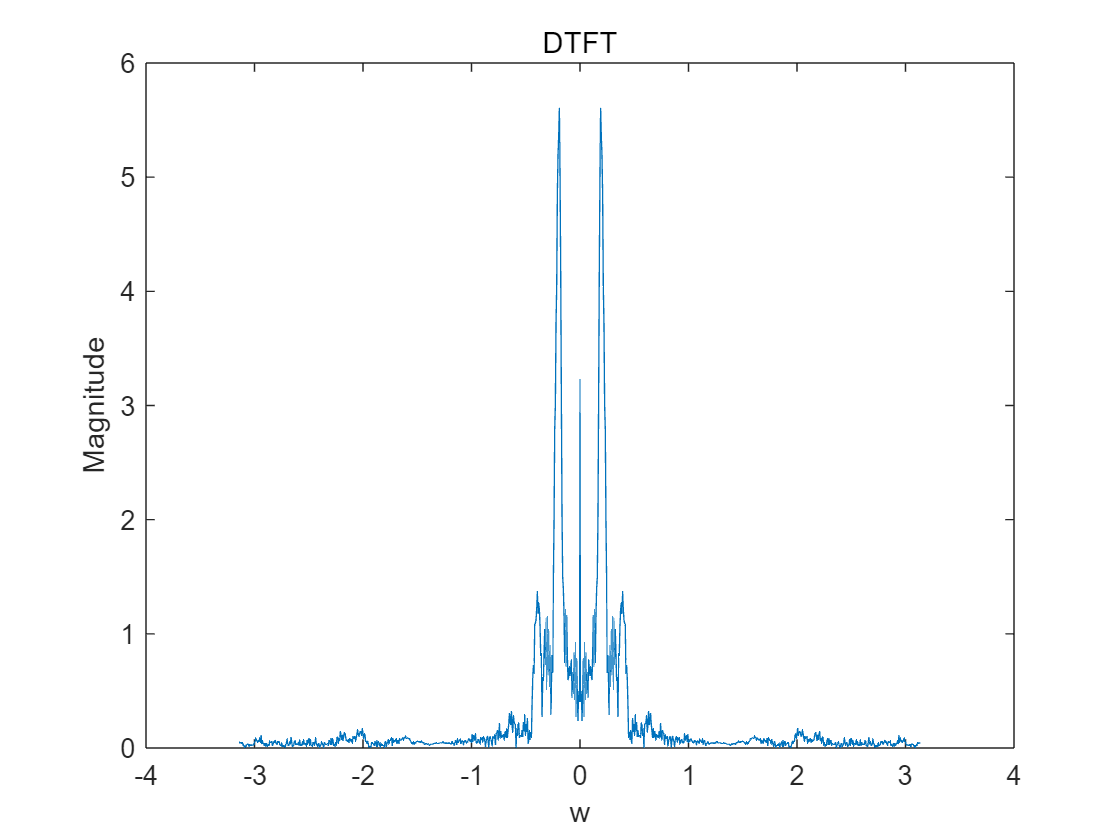

[X,w]=DTFT(nspeech1(100:1100),0);
figure;
plot(w,abs(X)),xlabel('w'),ylabel('Magnitude'),title('DTFT');

lowpass filter

the true signal magnitude can be recognized

## 7.4

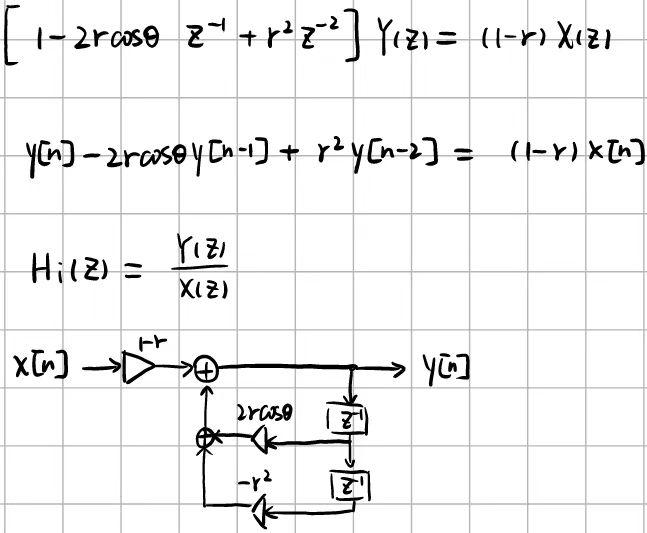

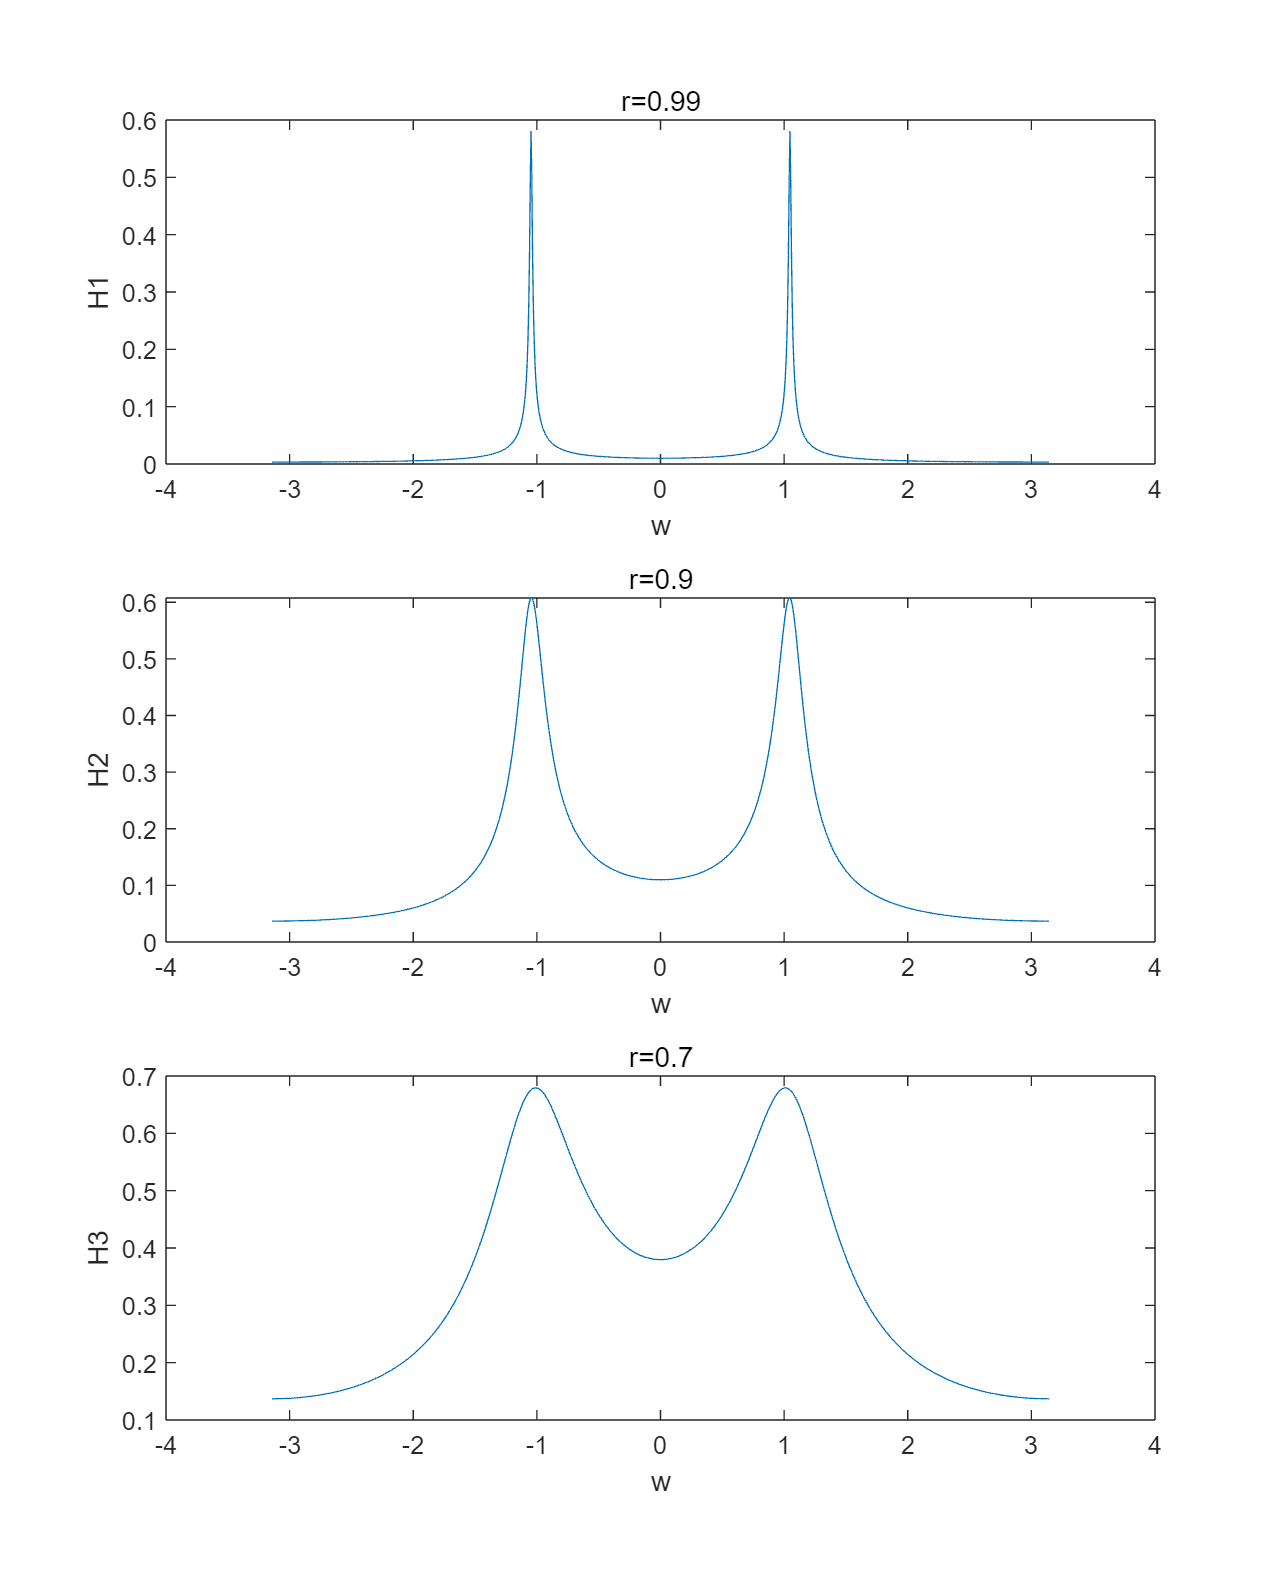

w = linspace(-pi,pi,1000);
z = exp(-1j*w);
r = 0.99;
H1 = (1-r)./(1-2*r*cos(pi/3)*z.^(-1)+r^2*z.^(-2));
r = 0.9;
H2 = (1-r)./(1-2*r*cos(pi/3)*z.^(-1)+r^2*z.^(-2));
r = 0.7;
H3 = (1-r)./(1-2*r*cos(pi/3)*z.^(-1)+r^2*z.^(-2));
figure('Position', [100 100 800 1000]);
subplot(311),plot(w,abs(H1)),xlabel('w'),ylabel('H1'),title('r=0.99');
subplot(312),plot(w,abs(H2)),xlabel('w'),ylabel('H2'),title('r=0.9');
subplot(313),plot(w,abs(H3)),xlabel('w'),ylabel('H3'),title('r=0.7');

r → 1, ideal; r decreases, maximum decreases, smooth

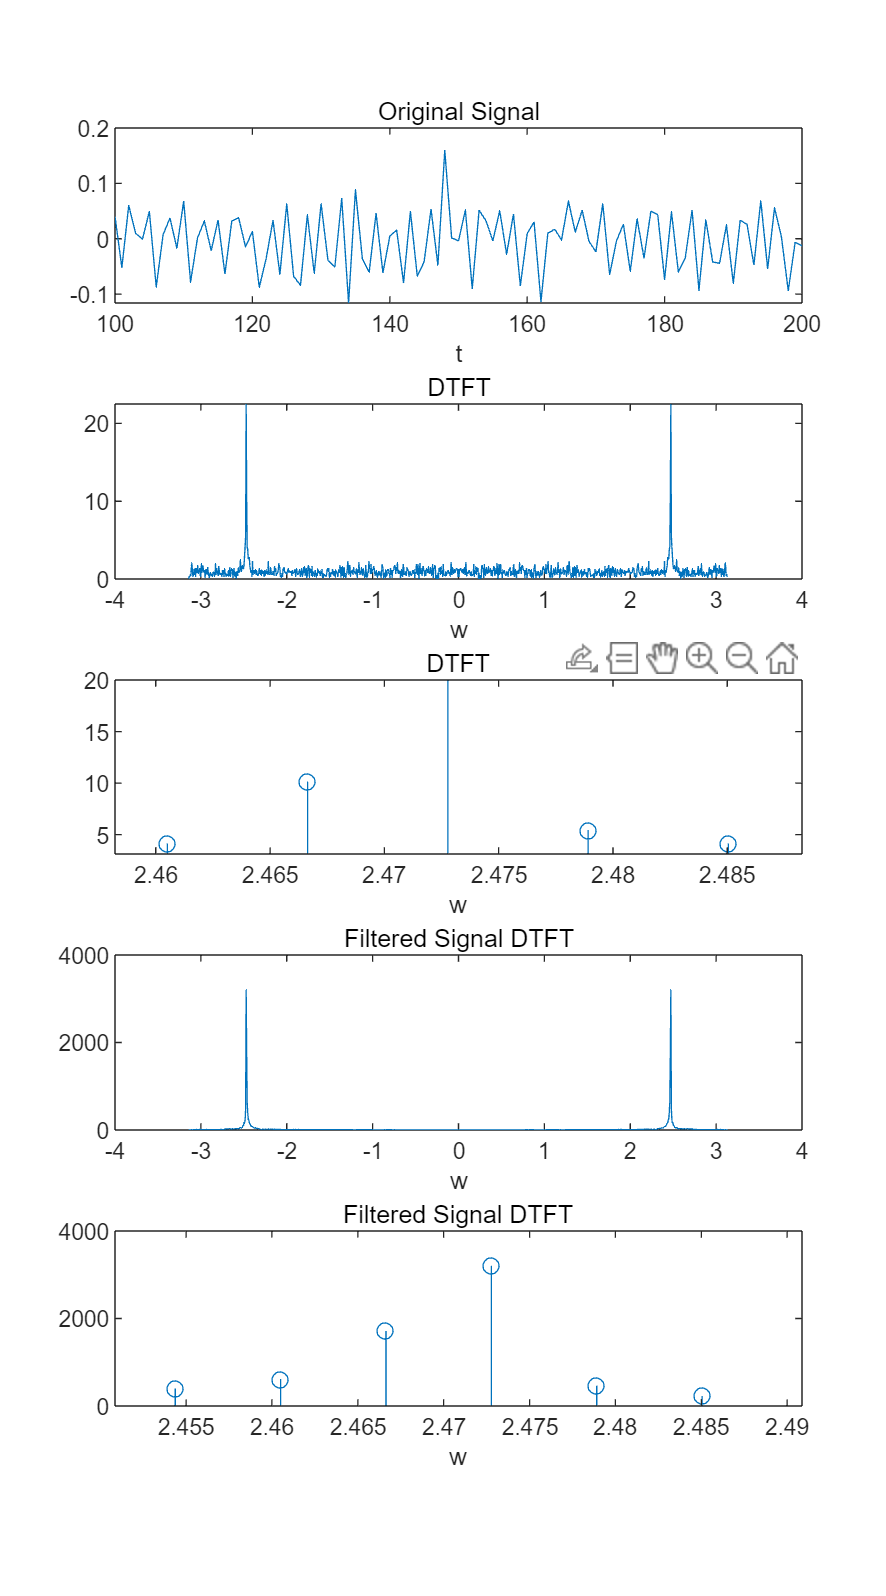

load pcm.mat;
sound(pcm);
sound(IIRfilter(pcm));
figure('Position', [100 100 1000 1800]);
subplot(511),plot(100:200,pcm(100:200)),xlabel('t'),title('Original Signal');
[X,w] = DTFT(pcm(100:1100),0);
subplot(512),plot(w,abs(X)),xlabel('w'),title('DTFT');
subplot(513),stem(w,abs(X)),xlabel('w'),title('DTFT'),xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);
[X,w] = DTFT(IIRfilter(pcm(100:1100)),0);
subplot(514),plot(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT');
subplot(515),stem(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT'),xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);

After filter, the noise over the frequency is reduced, and the sound can be heard more clearly.

if r = 0.99999999:

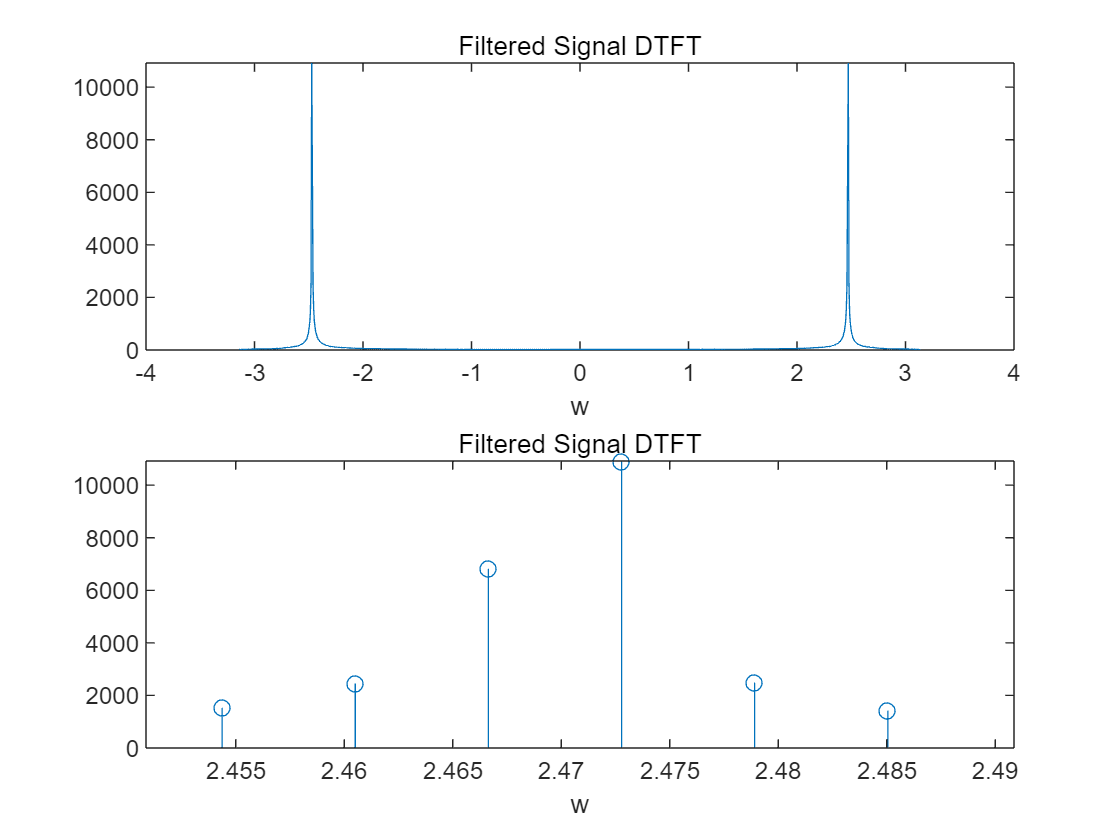

figure;
[X,w] = DTFT(IIRfilter2(pcm(100:1100)),0);
sound(IIRfilter2(pcm));
subplot(211),plot(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT');
subplot(212),stem(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT'),xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);

from the sound, it's du——, not du, du, du 

the magnitude is clearly changed around theta

## 7.6

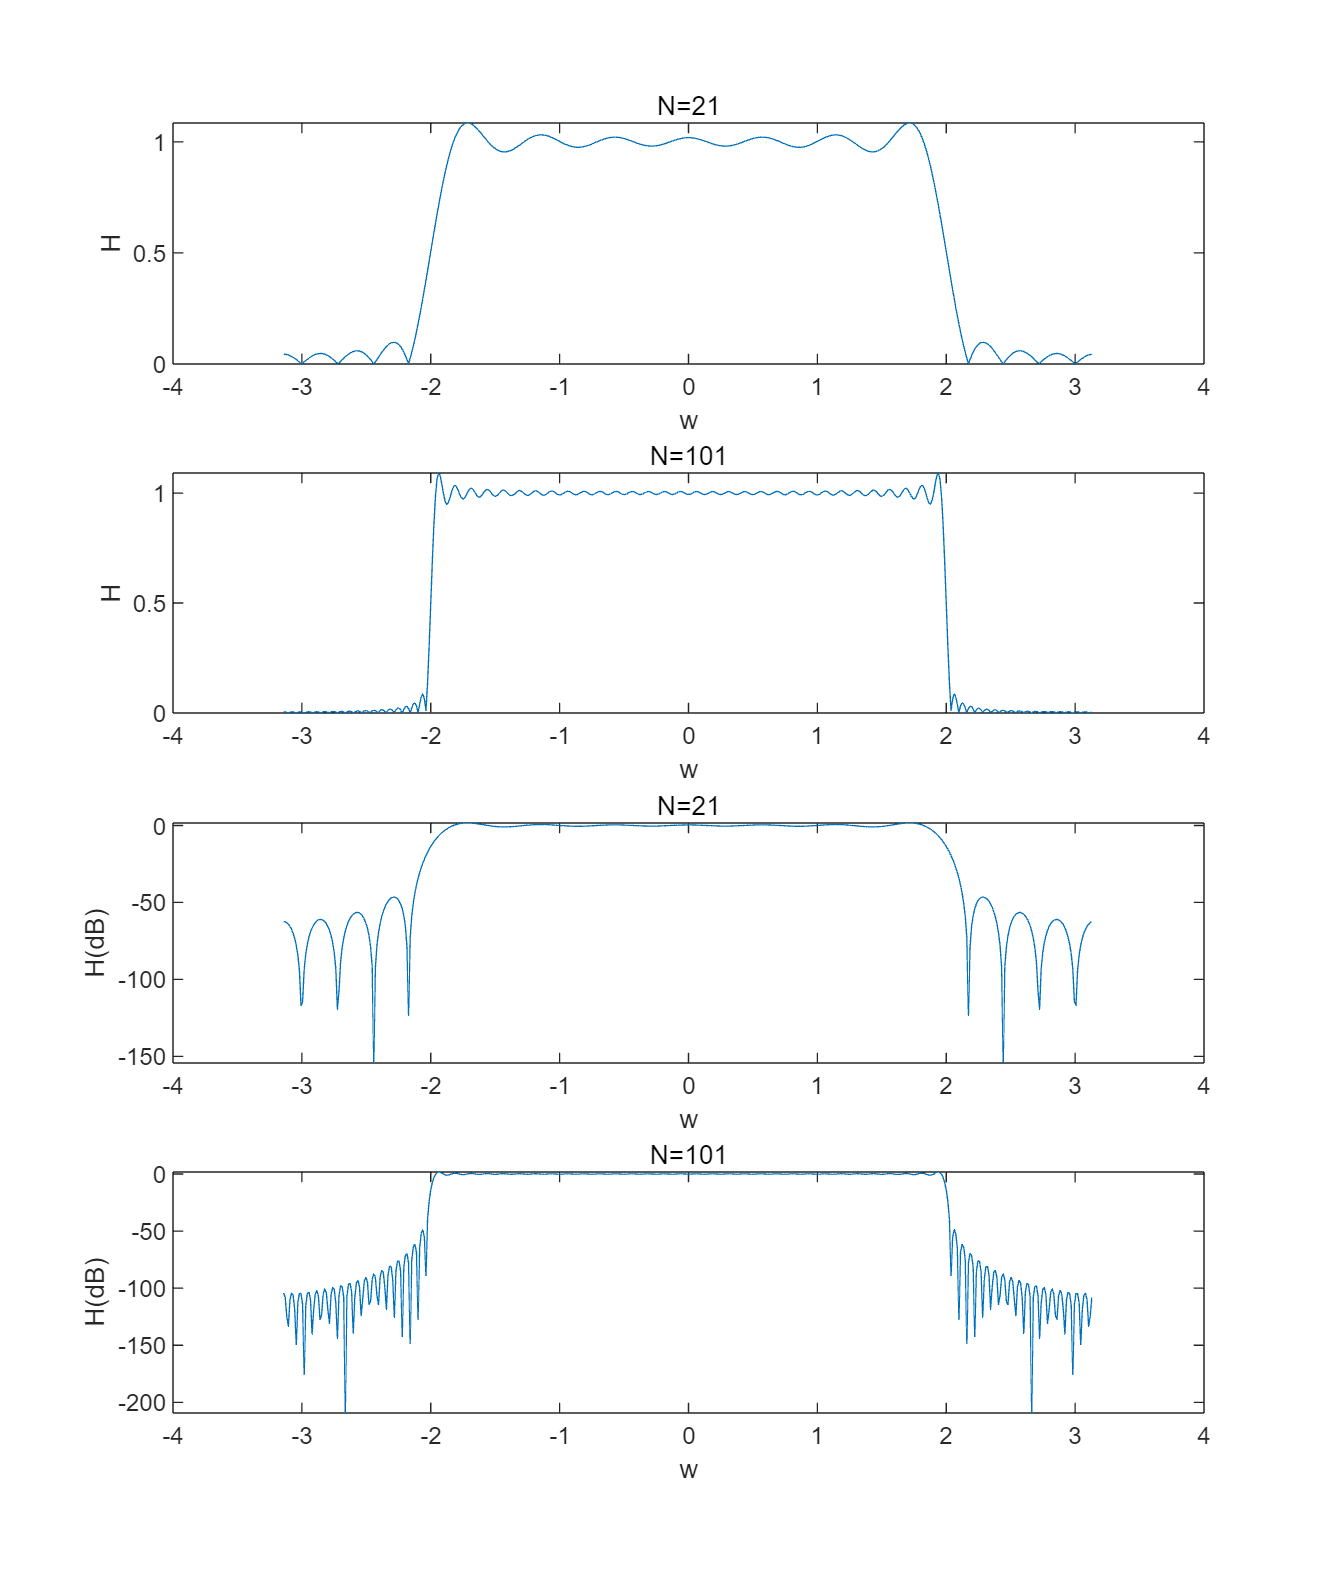

clc,clear,close all;
load nspeech2.mat;
sound(nspeech2);
N1 = 21;
N2 = 101;
h1 = LPFtrunc(N1);
[X1, w1] = DTFT(h1,512);
h2 = LPFtrunc(N2);
[X2, w2] = DTFT(h2,512);
figure('Position', [100 100 1000 1200]);
subplot(411),plot(w1,abs(X1)),xlabel('w'),ylabel('H'),title('N=21');
subplot(412),plot(w2,abs(X2)),xlabel('w'),ylabel('H'),title('N=101');
subplot(413),plot(w1,20*log(abs(X1))),xlabel('w'),ylabel('H(dB)'),title('N=21');
subplot(414),plot(w2,20*log(abs(X2))),xlabel('w'),ylabel('H(dB)'),title('N=101');

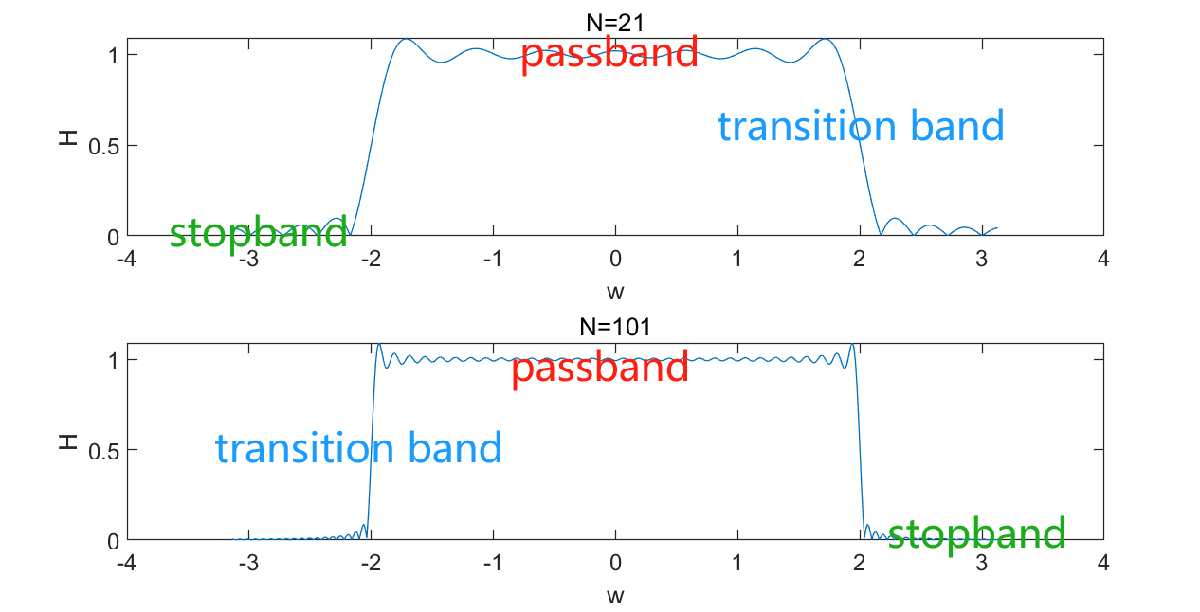

after filter, stopband more smooth

## 7.7

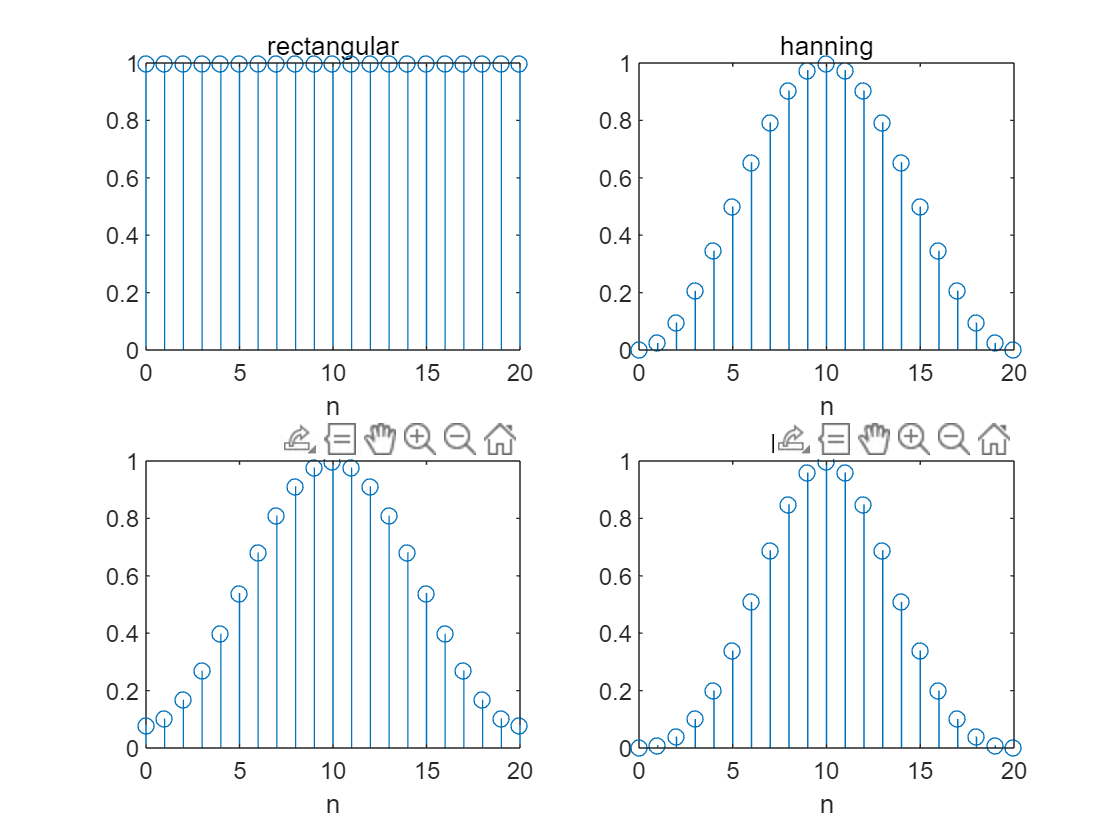

clc,clear,close all;
N = 0:20;
rectangular = ones(21, 1);
hanning = hann(21);
hamm = hamming(21);
blackm = blackman(21);
figure;
subplot(221),stem(N,rectangular),xlabel('n'),title('rectangular');
subplot(222),stem(N,hanning),xlabel('n'),title('hanning');
subplot(223),stem(N,hamm),xlabel('n'),title('hamming');
subplot(224),stem(N,blackm),xlabel('n'),title('blackman');

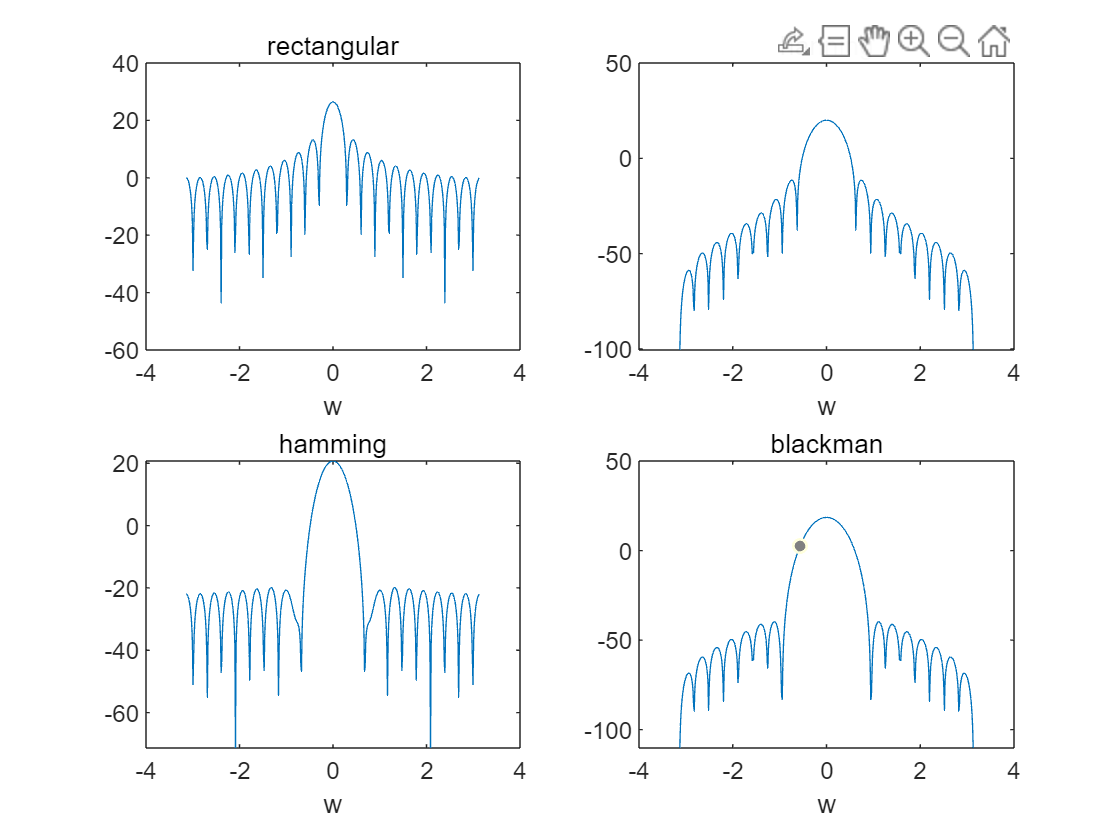

[X1, w1] = DTFT(rectangular, 512);
[X2, w2] = DTFT(hanning, 512);
[X3, w3] = DTFT(hamm, 512);
[X4, w4] = DTFT(blackm, 512);
figure;
subplot(221),plot(w1,20*log10(abs(X1))),xlabel('w'),title('rectangular');
subplot(222),plot(w2,20*log10(abs(X2))),xlabel('w'),title('hanning');
subplot(223),plot(w3,20*log10(abs(X3))),xlabel('w'),title('hamming');
subplot(224),plot(w4,20*log10(abs(X4))),xlabel('w'),title('blackman');

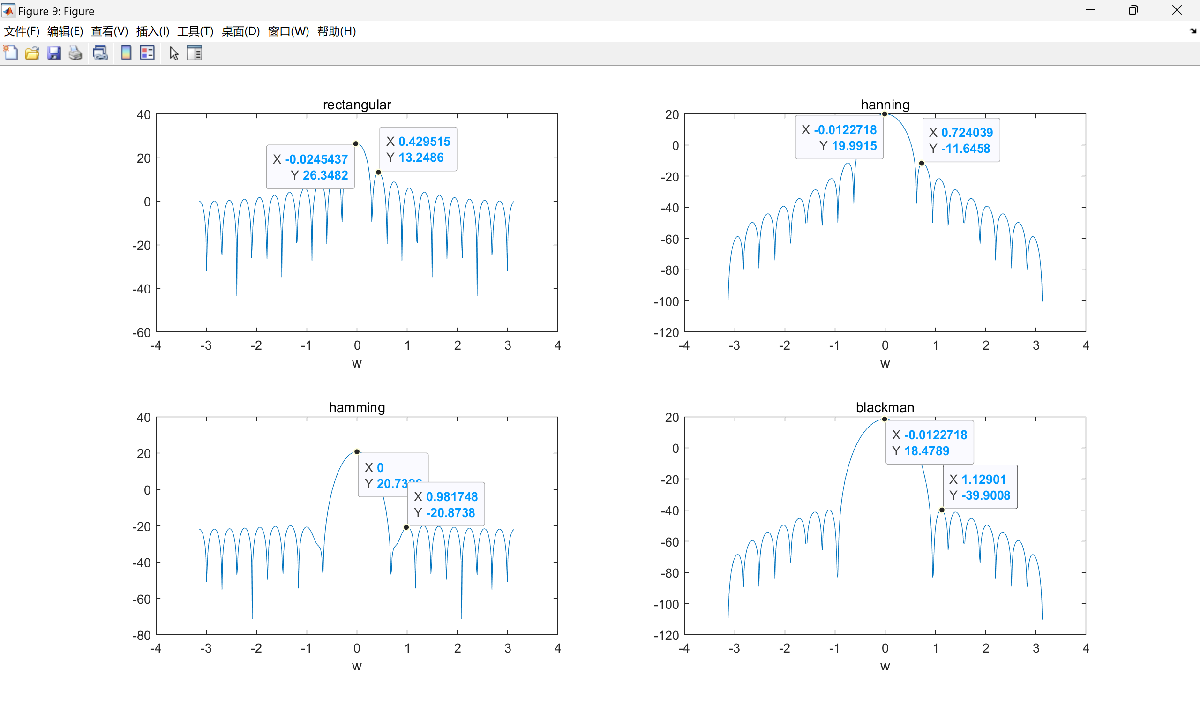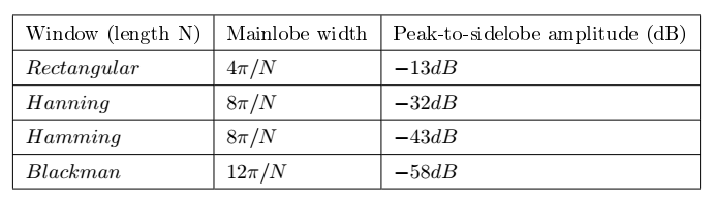

mainlobe width increase, peak-to-sidelobe amplitude increase

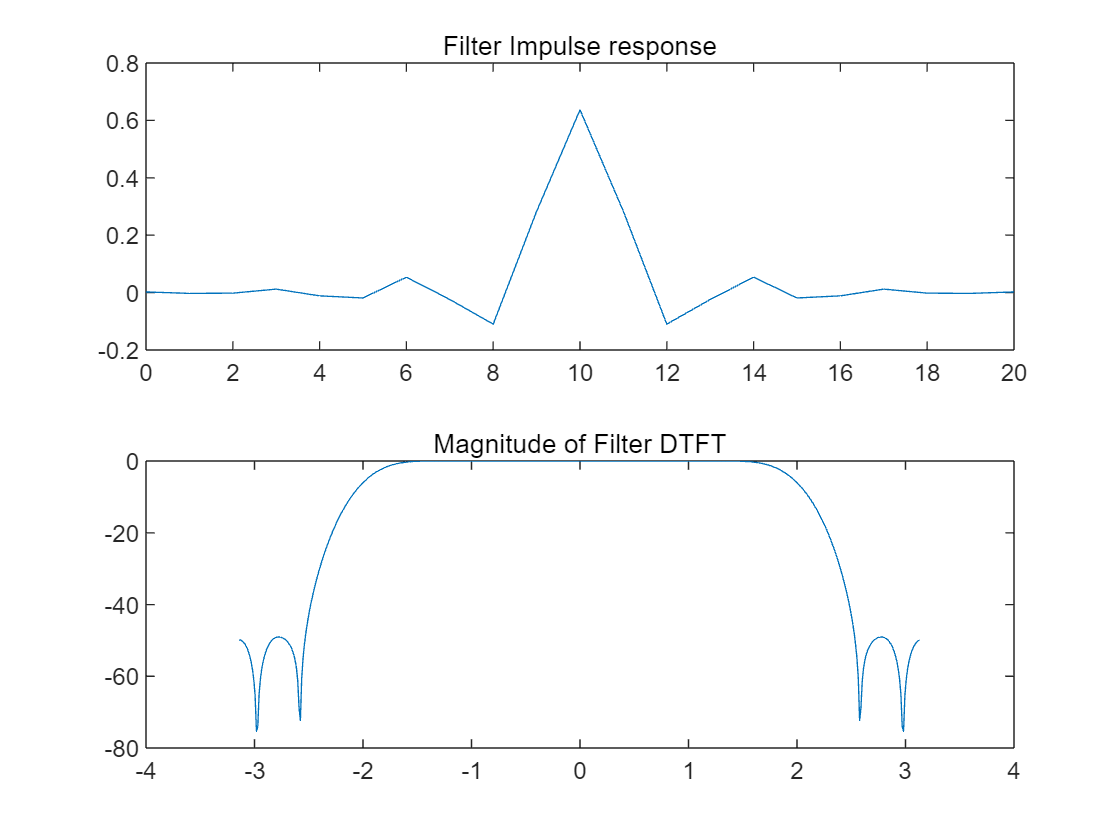

H = ((2/pi) .* sinc((2/pi) .* (N - (0.5 * (length(N) - 1)))))';
w = H .* hamm;
[X, W] = DTFT(w, 512);
figure;
subplot(211),plot(N, w),title('Filter Impulse response');
subplot(212),plot(W, 20*log10(abs(X))),title('Magnitude of Filter DTFT');

## 7.8

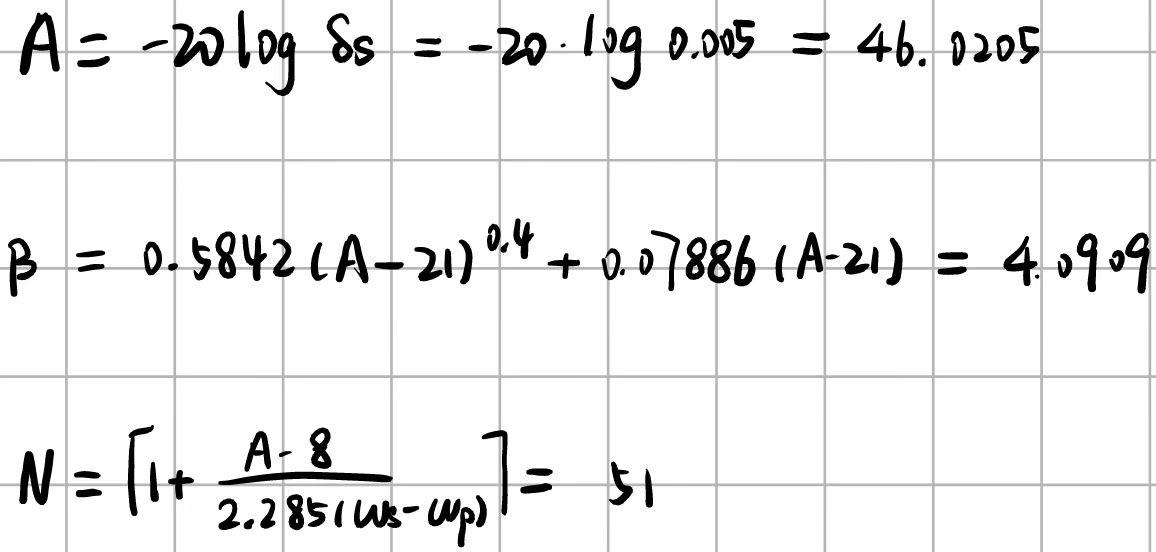

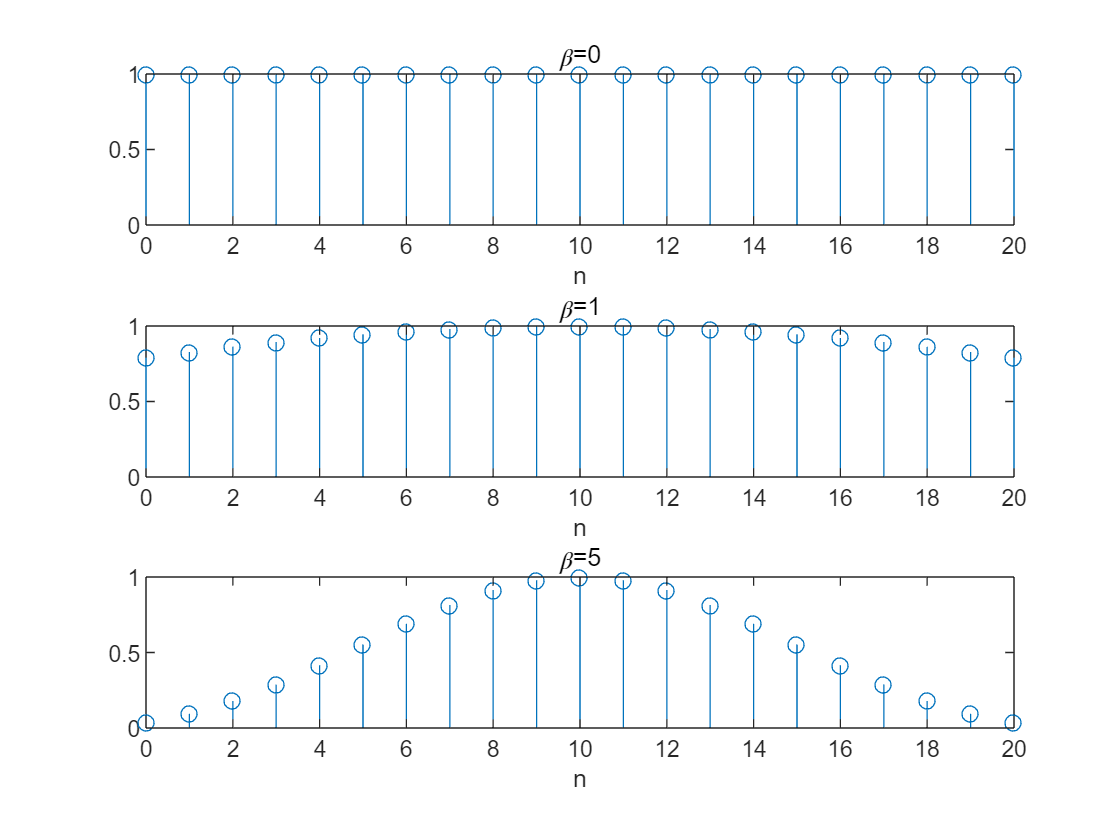

clc,clear,close all;
load nspeech2.mat;
n = 0:20;
kaiserWindow1 = kaiser(21, 0);
kaiserWindow2 = kaiser(21, 1);
kaiserWindow3 = kaiser(21, 5);
figure;
subplot(311),stem(n,kaiserWindow1),xlabel('n'),title('\beta=0');
subplot(312),stem(n,kaiserWindow2),xlabel('n'),title('\beta=1');
subplot(313),stem(n,kaiserWindow3),xlabel('n'),title('\beta=5');

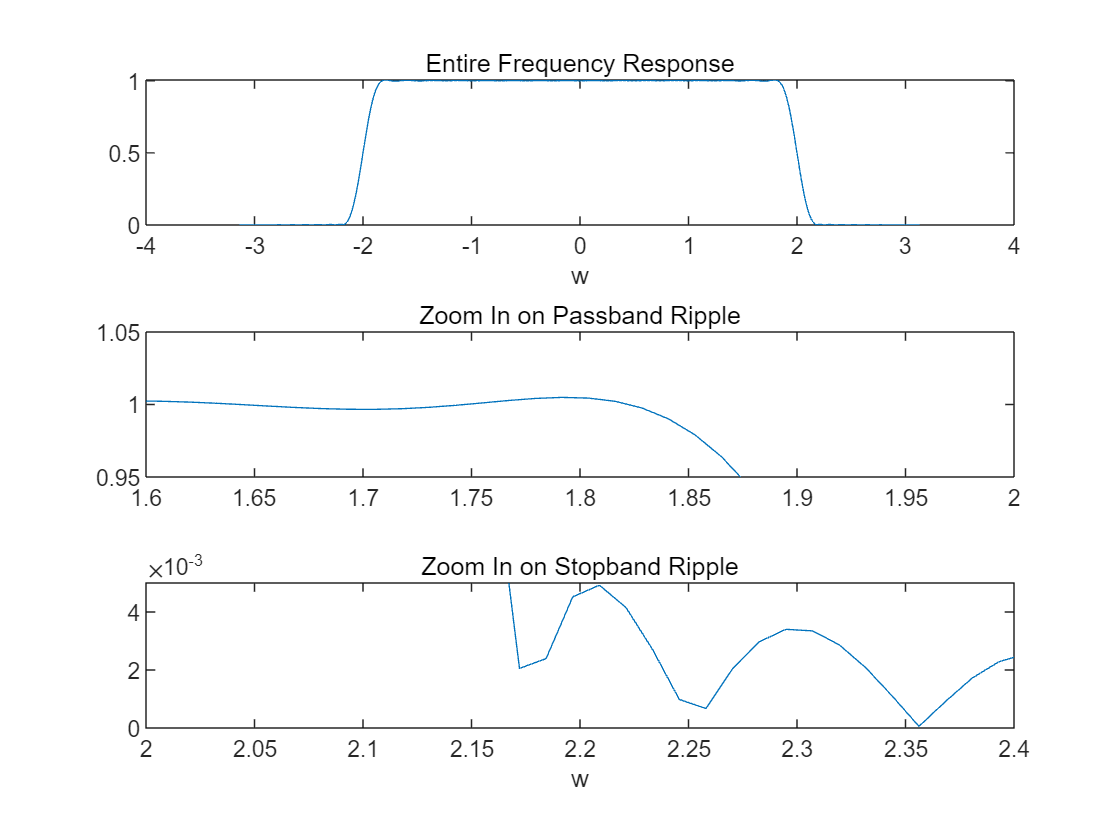

[X1, w1] = DTFT(kaiserWindow1, 512);
[X2, w2] = DTFT(kaiserWindow2, 512);
[X3, w3] = DTFT(kaiserWindow3, 512);
figure;
subplot(311),plot(w1,20*log10(abs(X1))),xlabel('w'),title('\beta=0');
subplot(312),plot(w2,20*log10(abs(X2))),xlabel('w'),title('\beta=1');
subplot(313),plot(w3,20*log10(abs(X3))),xlabel('w'),title('\beta=5');
omega_p = 1.8;
omega_c = 2.0;
omega_s = 2.2;
delta_p = 0.05;
delta_s = 0.005;
kaiserBeta = 4.0909;
filterOrder = 51;
kaiserWindow = kaiser(filterOrder, kaiserBeta);
filterImpulseResponse = LPFtrunc(filterOrder);
filteredFilter = filterImpulseResponse .* kaiserWindow';
[X, w] = DTFT(filteredFilter, 512);
subplot(311),plot(w, abs(X)),title('Entire Frequency Response'),xlabel('w');
subplot(312),plot(w, abs(X)),title('Zoom In on Passband Ripple'),axis([omega_p-0.2, omega_p+0.2, 1-delta_p, 1+delta_p]);
subplot(313),plot(w, abs(X)),title('Zoom In on Stopband Ripple'),xlabel('w'),axis([omega_s-0.2, omega_s+0.2, 0, delta_s]);

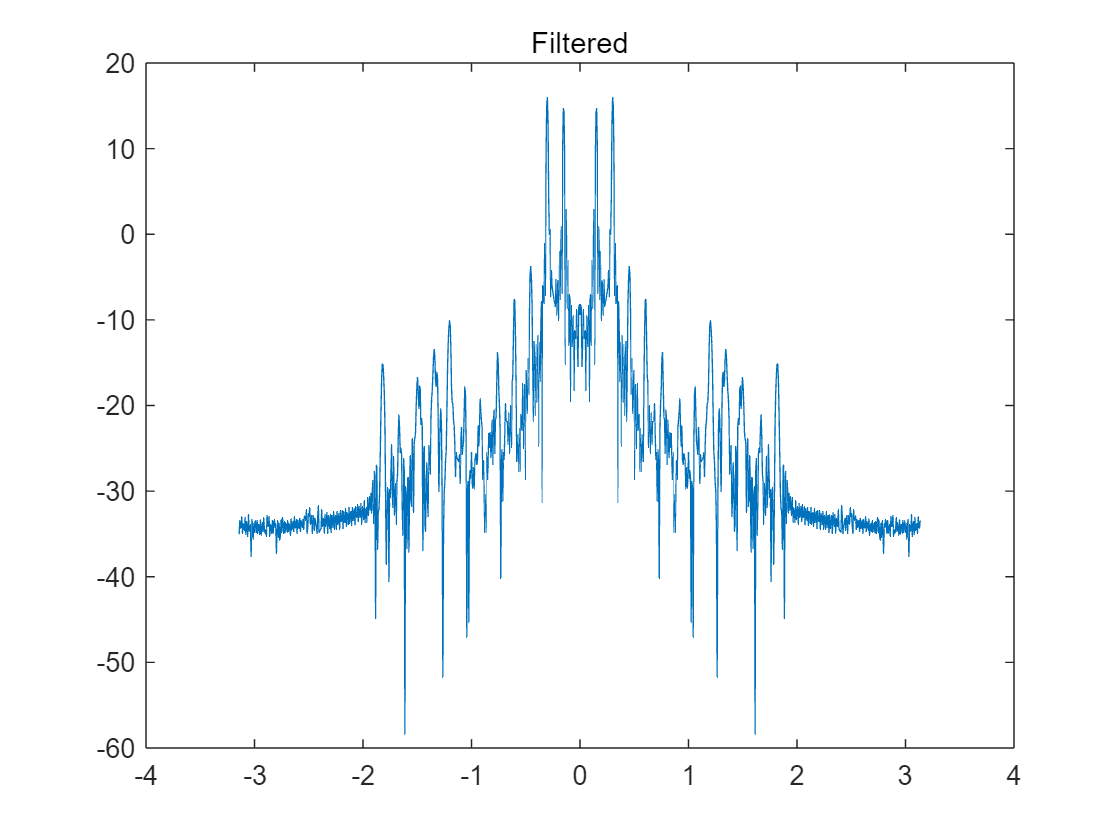

filteredSpeech = conv(filteredFilter, nspeech2);
[filteredDTFT, filteredOmega] = DTFT(filteredSpeech(20001:20400), 1024);
figure;
plot(filteredOmega, 20*log10(abs(filteredDTFT))),title('Filtered');

sound(nspeech2, 8000);
pause(length(nspeech2)/8000);
sound(filteredSpeech, 8000);

more clearly

function output = FIRfilter(x)
    [X,w] = DTFT(x,0);
    [Xmax,Imax] = max(abs(X));
    theta = w(Imax);
    h = [1, -2*cos(theta), 1];
    output = conv(x,h);
end

function y = IIRfilter(x)
    theta = (3146/8000)*2*pi;
    r = 0.995;
    N = length(x);
    y = zeros(1,N);
    y(1) = x(1);
    y(2) = x(2) + 2*r*cos(theta);
    for i = 3:N
        y(i) = x(i) + 2*r*cos(theta).*y(i-1) - (r^2).*y(i-2);
    end
end

function y = IIRfilter2(x)
    theta = (3146/8000)*2*pi;
    r = 0.99999999;
    N = length(x);
    y = zeros(1,N);
    y(1) = x(1);
    y(2) = x(2) + 2*r*cos(theta);
    for i = 3:N
        y(i) = x(i) + 2*r*cos(theta).*y(i-1) - (r^2).*y(i-2);
    end
end

function h = LPFtrunc(N)
    for i = 1:N
        h(i) = 2/pi*sinc(2/pi*(i-1-(N-1)/2));
    end
end